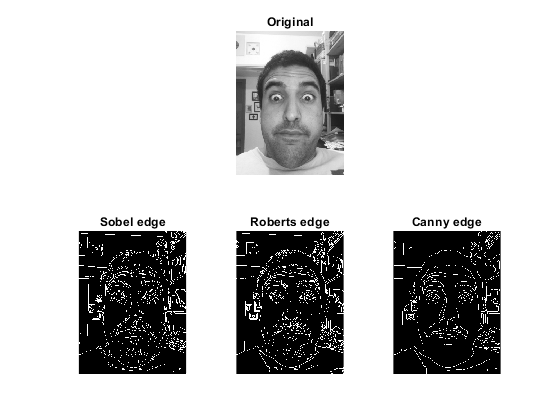

selfie = imread('IMG_4717.jpg');
selfie = imrotate(selfie,-90);
selfie = imresize(selfie,[400 300]);
selfie = rgb2gray(selfie);
selfie = imgaussfilt(selfie,0.5);
fig = figure;
subplot(2,3,2)
imshow(selfie)
title('Original')
subplot(2,3,4)
imshow(edge(selfie,'Sobel',0.03))
title('Sobel edge')
subplot(2,3,5)
imshow(edge(selfie,'Roberts',0.03))
title('Roberts edge')
subplot(2,3,6)
imshow(edge(selfie,'Canny',0.2))
title('Canny edge')
saveas(fig,'Q2-2.jpg')

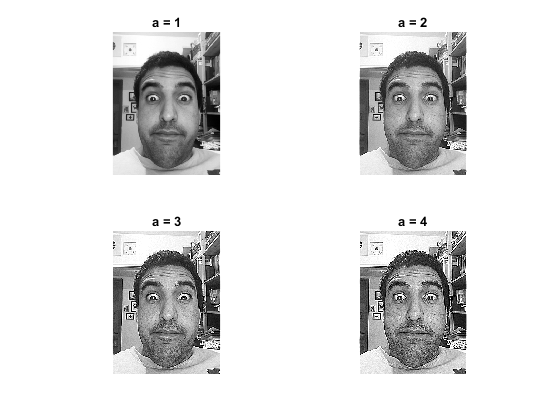

a = realp('a',-1);
op = [0 -a 0; -a 1+4*a -a; 0 -a 0];
vals = [0 1 2 3 4];
fig = figure();
for i = 1:1:4
    subplot(2,2,i)
    op.Blocks.a.Value = vals(i);
    tmp_img = imfilter(selfie,double(op));
    imshow(clip(tmp_img),[]);
    title(['a = ' num2str(i)])
end
saveas(fig,'Q2-3.jpg')

noised_selfie = imnoise(selfie,'salt & pepper',0.06)

noised_selfie = 400×300 uint8 matrix
   208   209   208   208   209   210   211   212   213   212   212   214   215   214   216   215   215   216   215   217   217   218   217   218   219   219   220   220   220   221   221   222   222     0   223   224   223   222   223   225   224   224   224   224   255   225   225   226   225   226
   207   207   207   207   208   210   210   211   212   212   212   213   214   214   216   216   215   216   216   217   217   217   218   218   220   221   221   255   221   222   221   222   222   224   223   223   224   224   224   224   224   225   225   224   225   225   255   226   226   226
   207   207   207   207   208   209     0   212   213   213   212   213   215   214   215   215   214     0   216   217   218   217     0   219   255   255   221   222   221   221   222   222   222   224   224   223   224   224   224   224     0   225   224   224   225   226   225   225   227   227
   208   209   209   209   209   210   212     0   213   214

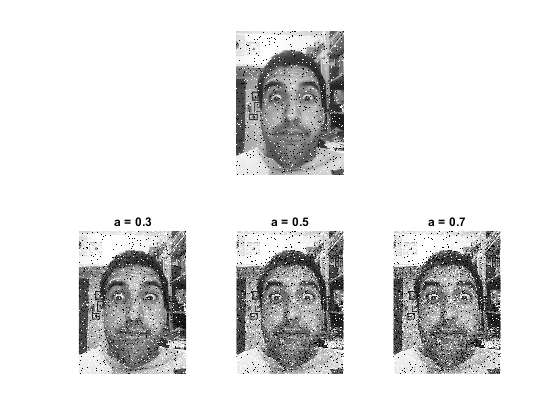

vals = [0.3 0.5 0.7];
fig = figure();
subplot(2,3,2)
imshow(noised_selfie,[])
for i = 1:1:3
    subplot(2,3,i+3)
    op.Blocks.a.Value = vals(i);
    tmp_img = imfilter(noised_selfie,double(op));
    imshow(clip(tmp_img),[]);
    title(['a = ' num2str(vals(i))])
end
saveas(fig,'Q2-4.jpg')

noised_filtered = medfilt2(noised_selfie)

noised_filtered = 400×300 uint8 matrix
     0   207   207   207   208   209   210   211   212   212   212   212   214   214   214   215   215   215   216   216   217   217   217   218   218   219   220   220   220   221   221   221   222   222   223   223   223   223   223   224   224   224   224   224   224   225   225   225   226   226
   207   207   207   208   208   209   210   212   212   212   212   213   214   215   215   215   215   215   216   217   217   217   218   218   219   221   221   221   221   221   222   222   222   223   223   223   224   224   224   224   224   224   224   224   225   225   225   226   226   226
   207   207   207   208   209   209   210   212   212   213   213   214   214   214   215   215   215   215   216   217   217   217   218   219   220   221   221   221   222   222   222   222   222   223   223   224   224   224   224   224   224   224   224   225   225   225   226   226   226   227
   207   209   209   209   209   210   212   213   213   2

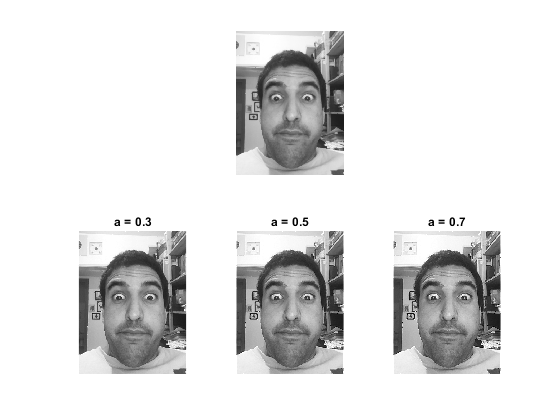

vals = [0.3 0.5 0.7];
fig = figure();
subplot(2,3,2)
imshow(noised_filtered,[])
for i = 1:1:3
    subplot(2,3,i+3)
    op.Blocks.a.Value = vals(i);
    tmp_img = imfilter(noised_filtered,double(op));
    imshow(clip(tmp_img),[]);
    title(['a = ' num2str(vals(i))])
end
saveas(fig,'Q2-5.jpg')